# **Lab3 - Prototip RCAM**

## **Hai cu putina teorie**

Aici o sa discutam despre un aviom civil si anume Modelul RCAM proiectat de GARTEUR

### Partea de modelare

Reprezentarea evolutiei sustemului sub forma$\left\lbrace \begin{array}{l}
\dot{x} \left(t\right)=g\left(x\left(t\right),u\left(t\right),d\left(t\right),f\left(t\right)\right)\\
y\left(t\right)=h\left(x\left(t\right),u\left(t\right),d\left(t\right),f\left(t\right)\right)
\end{array}\right.$, unde $\left\lbrace \begin{array}{l}
\left\lbrace \begin{array}{l}
x\in {\mathbb{R}}^n \\
u\in {\mathbb{R}}^m \\
y\in {\mathbb{R}}^p 
\end{array}\right.\\
\left\lbrace \begin{array}{l}
d\left(t\right)\;\textrm{sunt}\;\textrm{perturbatii}\\
f\left(t\right)\;\textrm{sunt}\;\textrm{avarii}\;/\;\textrm{defecte}
\end{array}\right.
\end{array}\right.$. Pentru modelarea initiala, consideram dinamica simplificata$\left\lbrace \begin{array}{l}
\dot{x} =g\left(x\left(t\right),u\left(t\right)\right)\\
y=x\left(t\right)
\end{array}\right.$. **Ipoteze simplificate: dinamica decuplabila, corp rigid, senzorii merg perfect, nu exista vant si alte perturbatii, etc**

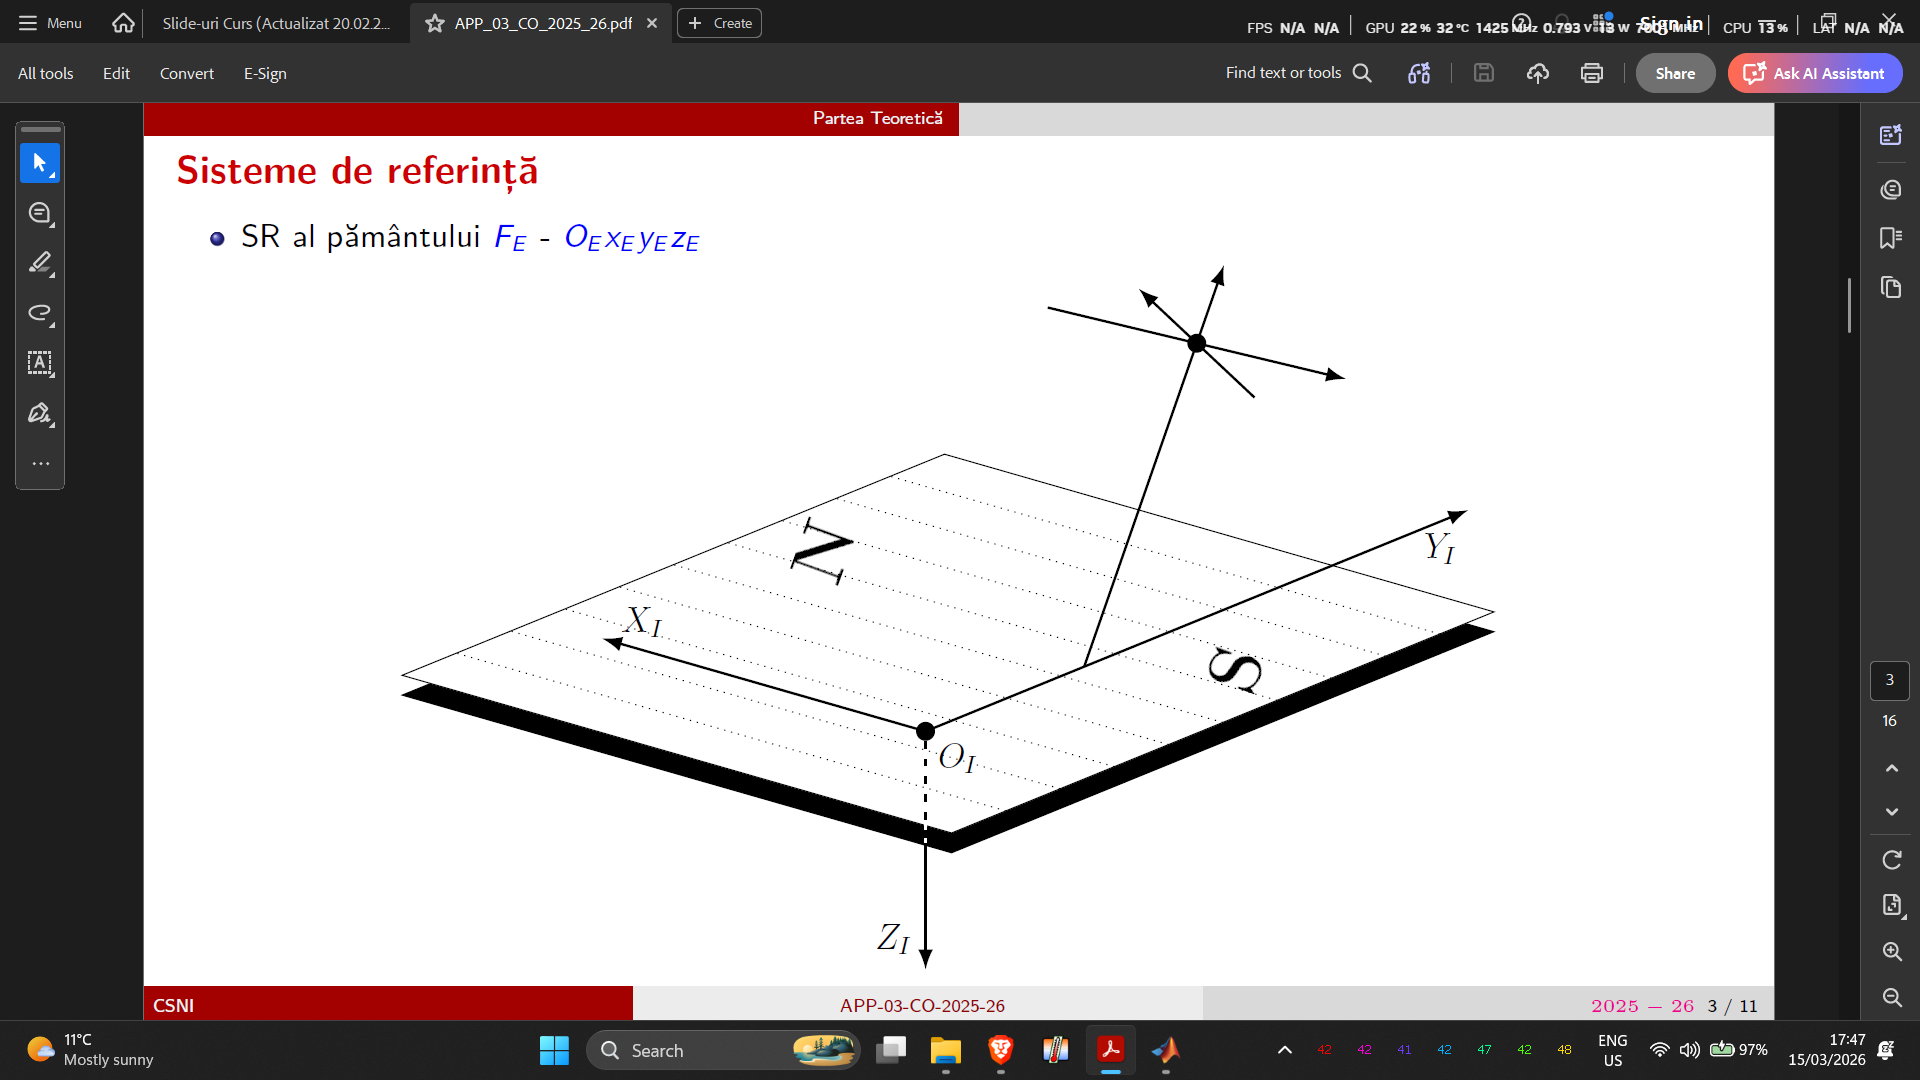

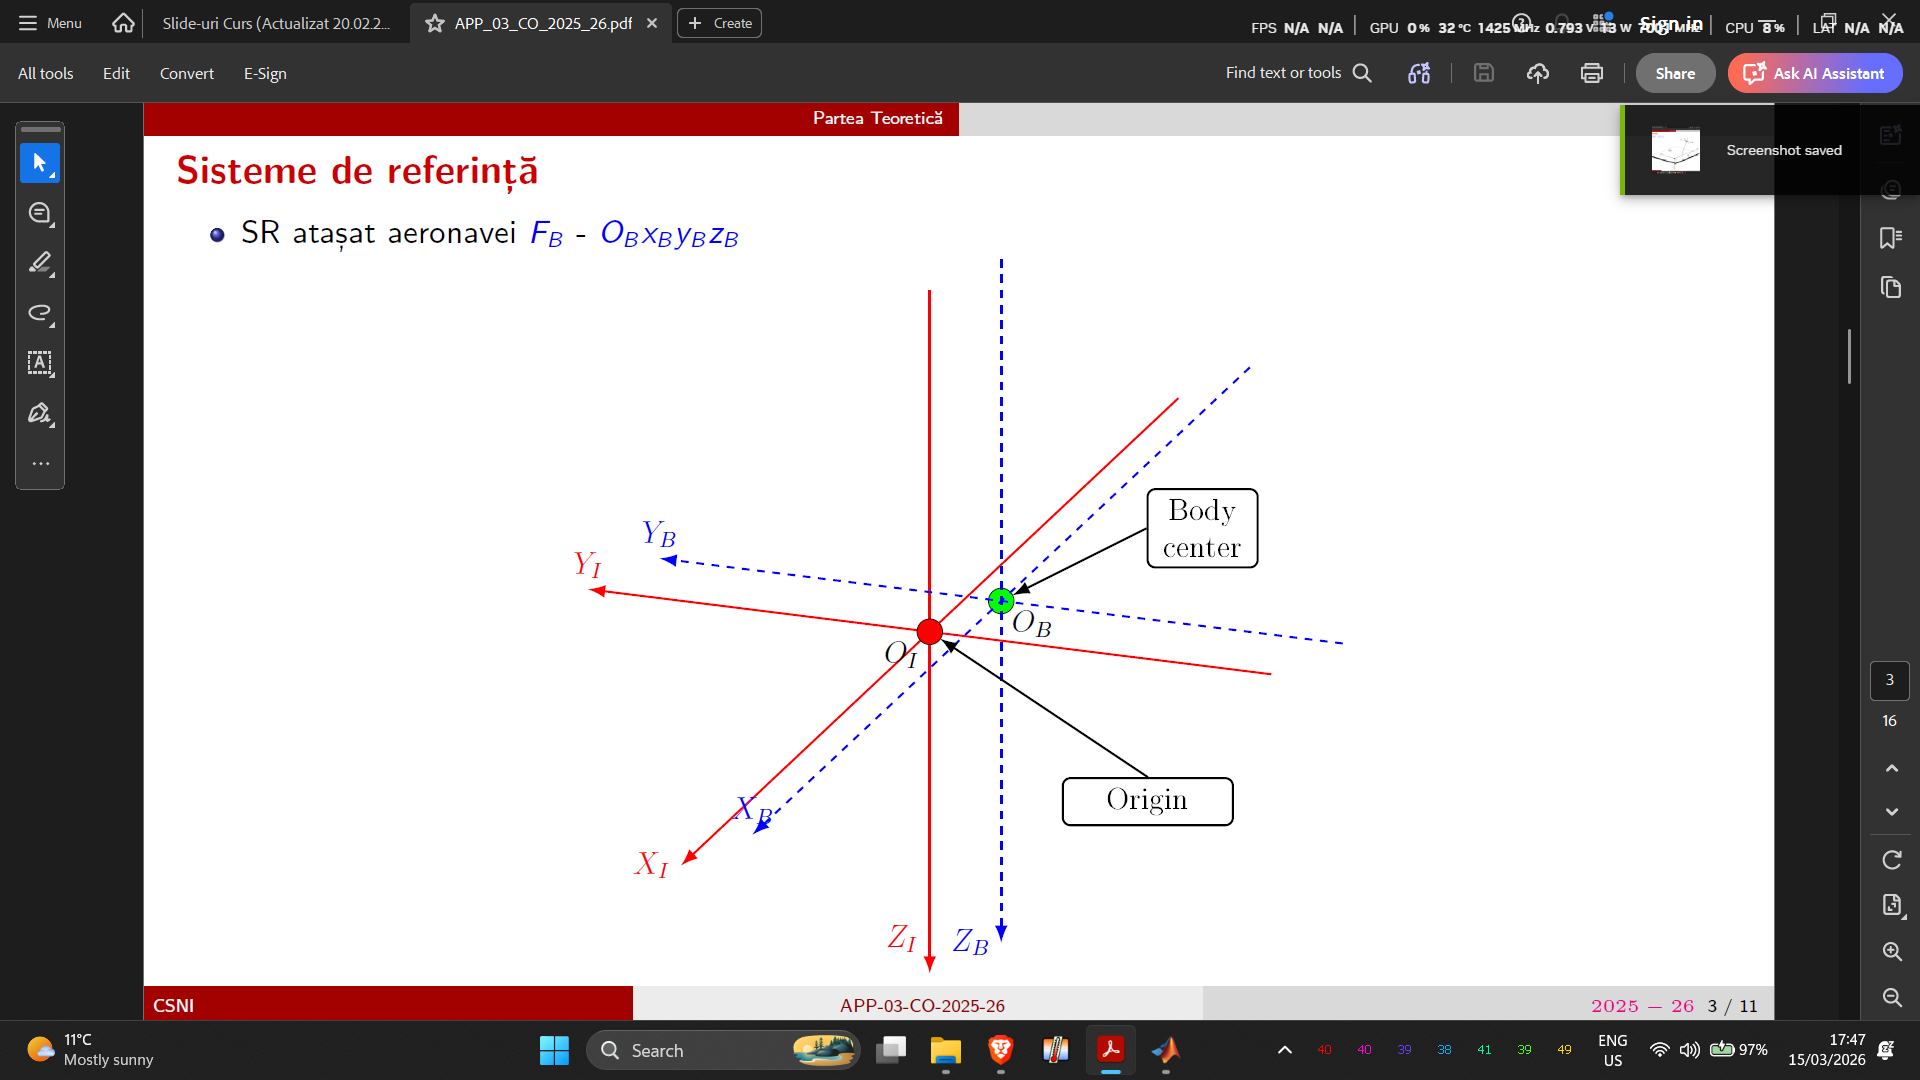

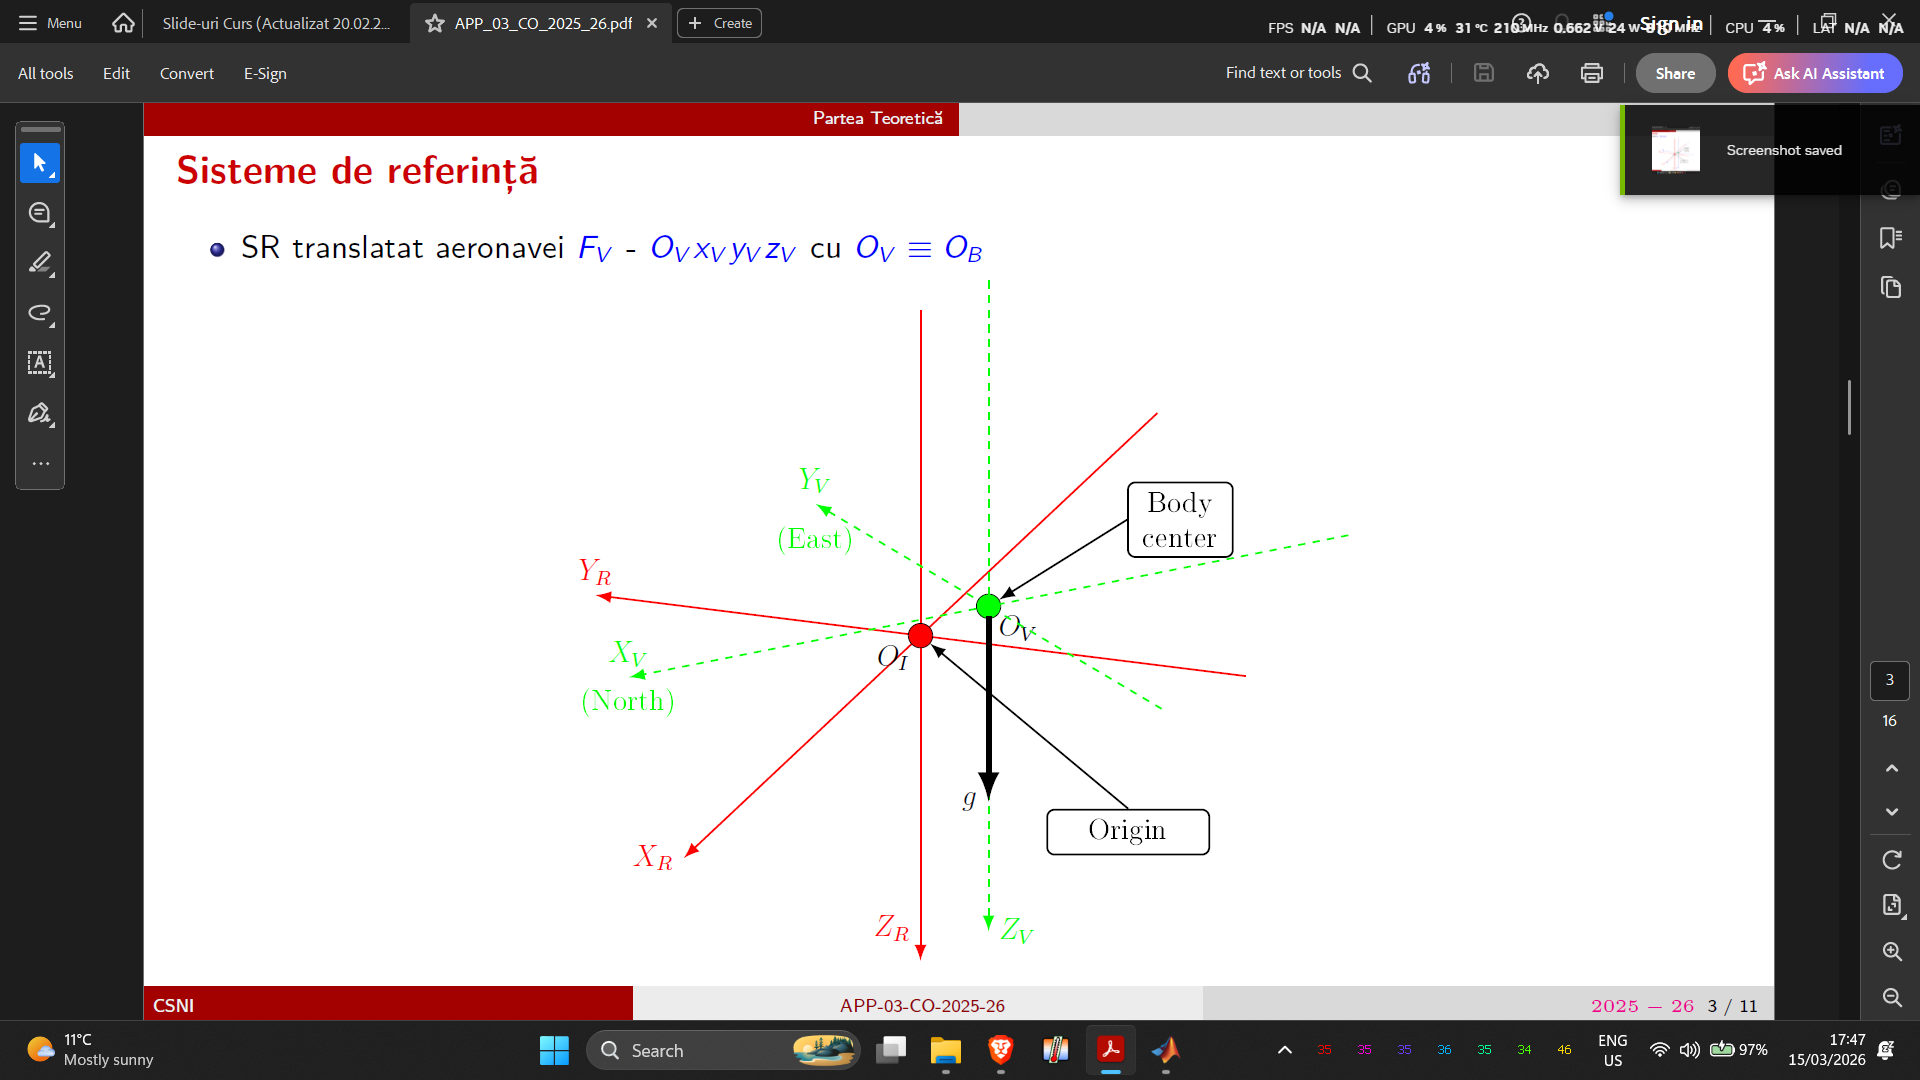

## Acum trebuie sa transformam coordonatele din $F_B \;\mathrm{in}\;F_V$

Unghiurile Euler $\Xi ={\left\lbrack \begin{array}{ccc}
\Phi  & \Theta  & \Psi 
\end{array}\right\rbrack }^T$, unde $\left\lbrace \begin{array}{l}
\Phi =\mathrm{rului}\;\left(\mathrm{roll}\right)\\
\Theta =\mathrm{tangaj}\;\left(\mathrm{pitch}\right)\\
\Psi =\mathrm{giratie}\;\left(\mathrm{yaw}\right)
\end{array}\right.$. Transformarea Euler intre $F_B \;\mathrm{si}\;F_V$:$R_{\mathrm{BV}} =R_1 \left(\Phi \right)R_2 \left(\Theta \right)R_3 \left(\Psi \right)$, unde $R_i ,i\in \overline{1,3}$.

**Fun fact:** In mod normal se folosesc cuaternioni pentru asta. Mult mai stabil numeric si mai usor de reprezentat

#### Model liniar pentru miscare longitudinala

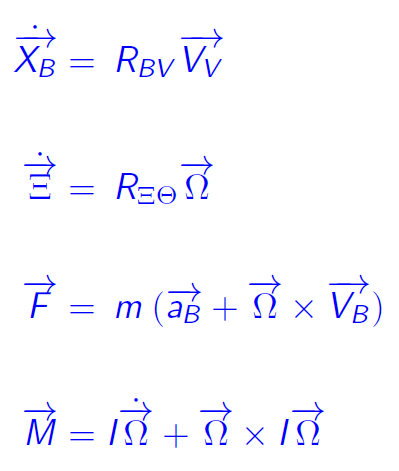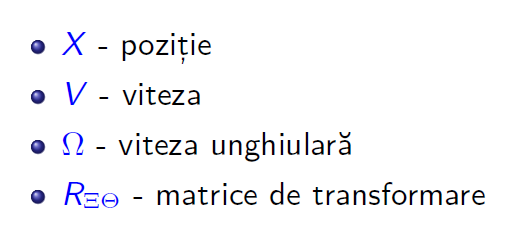

Acest model este extrem de neliniar, inadecvat pentru analiza si sinteza liniara

O solutie: liniarizare (teorema perturbatiilor mici) $\begin{array}{l}
\dot{x} \left(t\right)=A_{\mathrm{lon}} x\left(t\right)+B_{\mathrm{lon}} u\left(t\right)\\
y\left(t\right)=C_{\mathrm{lon}} x\left(t\right)+D_{\mathrm{lon}} u\left(t\right)
\end{array}$

Avem:

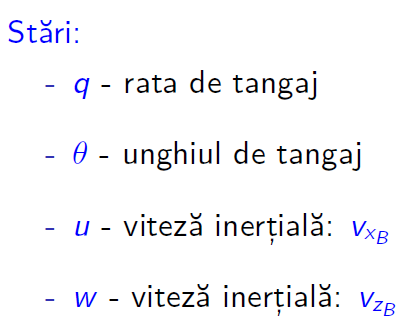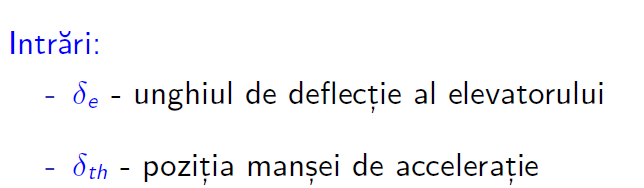

Acum la lateral (mi-e lene sa scriu)

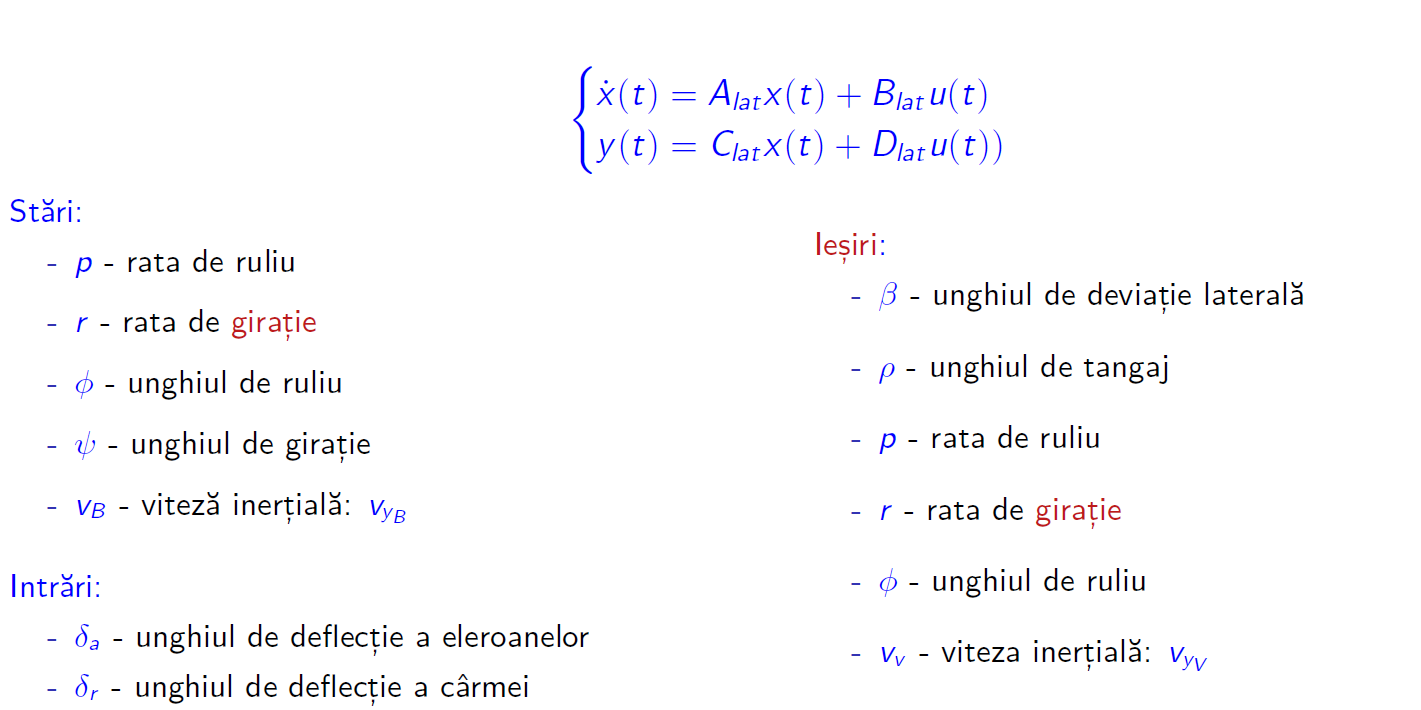

## **Primul exercitiu**

clear
close all
clc

load("E:\Radu editing document\SS + TCAI + TSA\CO + RSA\CO+RSA\CO+RSA\CO\Lab_Daniel\RCAM.mat")
disp('valorile + vectori proprii ale lui A_lat');

valorile + vectori proprii ale lui A_lat


[V_lat, Lamlat] = eig(A_lat)

V_lat =   -0.7984 + 0.0000i  -0.0171 + 0.0072i  -0.0171 - 0.0072i   0.0160 + 0.0000i  -0.0000 + 0.0000i
   0.0508 + 0.0000i   0.0028 - 0.0047i   0.0028 + 0.0047i  -0.0106 + 0.0000i   0.0000 + 0.0000i
   0.5975 + 0.0000i   0.0201 + 0.0205i   0.0201 - 0.0205i  -0.0895 + 0.0000i   0.0000 + 0.0000i
  -0.0381 + 0.0000i  -0.0085 - 0.0014i  -0.0085 + 0.0014i   0.0601 + 0.0000i  -1.0000 + 0.0000i
   0.0385 + 0.0000i   0.9994 + 0.0000i   0.9994 + 0.0000i  -0.9940 + 0.0000i   0.0000 + 0.0000i


Lamlat =   -1.3338 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.2401 + 0.5955i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.2401 - 0.5955i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.1760 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i



disp('valorile + vectori proprii ale lui A_lon');

valorile + vectori proprii ale lui A_lon


[V_lon, Lamlon] = eig(A_lon)

V_lon =    0.0019 - 0.0143i   0.0019 + 0.0143i  -0.0017 + 0.0003i  -0.0017 - 0.0003i
  -0.0091 + 0.0051i  -0.0091 - 0.0051i   0.0036 + 0.0128i   0.0036 - 0.0128i
  -0.0158 + 0.0015i  -0.0158 - 0.0015i  -0.9894 + 0.0000i  -0.9894 + 0.0000i
  -0.9997 + 0.0000i  -0.9997 + 0.0000i   0.1442 - 0.0058i   0.1442 + 0.0058i


Lamlon =   -0.8300 + 1.1023i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.8300 - 1.1023i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0115 + 0.1278i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0115 - 0.1278i



disp('Coeficient de amortizare si frecventa pentru lat');

Coeficient de amortizare si frecventa pentru lat


sys_lat = ss(A_lat, B_lat, C_lat, D_lat);

[wn_lat, zeta_lat, p_lat] = damp(sys_lat)

wn_lat =     0.0000
    0.1760
    0.6421
    0.6421
    1.3338


zeta_lat =     1.0000
    1.0000
    0.3739
    0.3739
    1.0000


p_lat =   -0.0000 + 0.0000i
  -0.1760 + 0.0000i
  -0.2401 + 0.5955i
  -0.2401 - 0.5955i
  -1.3338 + 0.0000i



isstable(sys_lat)

ans = logical
   1



disp('Coeficient de amortizare si frecventa pentru lon');

Coeficient de amortizare si frecventa pentru lon


sys_lon = ss(A_lon, B_lon, C_lon, D_lon);

[wn_lon, zeta_lon, p_lon] = damp(sys_lon)

wn_lon =     0.1283
    0.1283
    1.3798
    1.3798


zeta_lon =     0.0897
    0.0897
    0.6015
    0.6015


p_lon =   -0.0115 + 0.1278i
  -0.0115 - 0.1278i
  -0.8300 + 1.1023i
  -0.8300 - 1.1023i



isstable(sys_lon)

ans = logical
   1


## Al doilea exercitiu

Inpuls si treapta la Plat

Plat = ss(A_lat,B_lat,C_lat,D_lat)


Plat =
 
  A = 
             x1        x2        x3        x4        x5
   x1      -1.3      0.55    -2e-15    -2e-15    -0.024
   x2     0.052     -0.52   3.6e-16   3.7e-16    0.0045
   x3         1     0.028   2.3e-22         0         0
   x4         0         1   8.1e-21         0         0
   x5       2.3       -80       9.8  -1.4e-14     -0.17
 
  B = 
           u1      u2
   x1   -0.84    0.29
   x2  -0.018   -0.33
   x3       0       0
   x4       0       0
   x5       0       2
 
  C = 
          x1     x2     x3     x4     x5
   y1      0      0  1e-15  1e-15  0.012
   y2      1      0      0      0      0
   y3      0      1      0      0      0
   y4      0      0      1      0      0
   y5      0      0   -2.3     80      1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
   y4   0   0
   y5   0   0
 
Continuous-time state-space model.


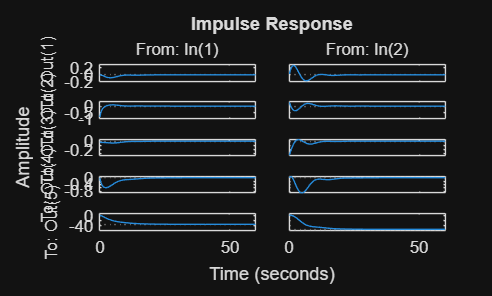


figure
impulse(Plat);

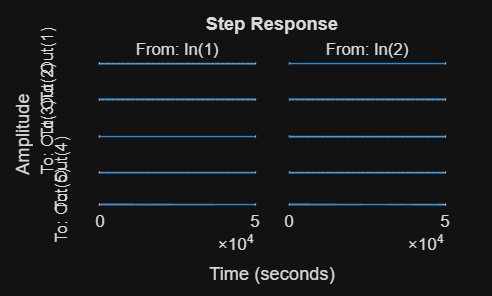


figure
step(Plat)

Impuls sis treapta la Plon

Plon = ss(A_lon,B_lon,C_lon,D_lon)


Plon =
 
  A = 
             x1        x2        x3        x4
   x1     -0.98   1.1e-15  -0.00065    -0.016
   x2         1         0         0         0
   x3      -2.2      -9.8    -0.033     0.074
   x4        77     -0.77     -0.23     -0.67
 
  B = 
         u1    u2
   x1  -2.4  0.29
   x2     0     0
   x3  0.18   9.8
   x4  -6.5     0
 
  C = 
             x1        x2        x3        x4
   y1         1         0         0         0
   y2         0       -80    -0.028         1
   y3         0  -1.4e-13         1     0.029
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
 
Continuous-time state-space model.


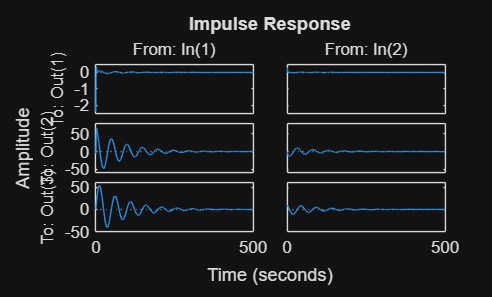


figure
impulse(Plon);

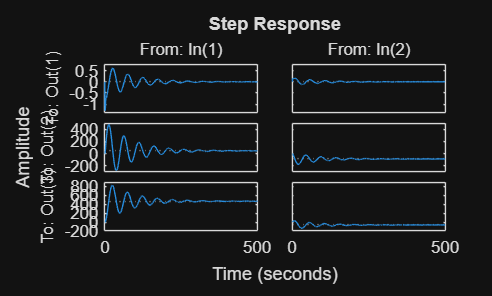


figure
step(Plon)

## Al treilea exercitiu

### Pentru lat

size(A_lat)

ans =      5     5



Pc_lat = ctrb(A_lat, B_lat);
disp('Rangul matricii de ctrc pe lat');

Rangul matricii de ctrc pe lat


rank(Pc_lat)

ans = 5


Po_lat = obsv(A_lat, C_lat);
disp('Rangul matricii de obsv pe lat');

Rangul matricii de obsv pe lat


rank(Po_lat)

ans = 5

Se observa ca sistemul este minimal, deci este si stailizabil si detectabil

### Pentru lon

size(A_lon)

ans =      4     4



Pc_lon = ctrb(A_lon, B_lon);
disp('Rangul matricii de ctrc pe lat');

Rangul matricii de ctrc pe lat


rank(Pc_lon)

ans = 4


Po_lon = obsv(A_lon, C_lon);
disp('Rangul matricii de obsv pe lat');

Rangul matricii de obsv pe lat


rank(Po_lon)

ans = 4

Se observa ca sistemul este minimal, deci este si stailizabil si detectabil

## Al patrulea exercitiu

### 
$$\left\lbrace -1-2-3-4\;\left(-\textrm{ceva}\right)\right\rbrace$$


Pentru lon

F_lon = -place(A_lon, B_lon, [-1 -2 -3 -4])

F_lon =     1.6039    0.0788   -0.0342    0.0106
   -5.2716  -39.1181   -0.2922    0.2295



disp(eig(A_lon + B_lon * F_lon))

   -4.0000
   -1.0000
   -2.0000
   -3.0000




Plon1 = ss(A_lon + B_lon * F_lon, B_lon, C_lon, D_lon)


Plon1 =
 
  A = 
              x1         x2         x3         x4
   x1     -6.358     -11.53   -0.00326    0.02518
   x2          1          0          0          0
   x3     -53.57     -393.1     -2.903      2.325
   x4      66.57     -1.282  -0.007546    -0.7388
 
  B = 
         u1    u2
   x1  -2.4  0.29
   x2     0     0
   x3  0.18   9.8
   x4  -6.5     0
 
  C = 
             x1        x2        x3        x4
   y1         1         0         0         0
   y2         0       -80    -0.028         1
   y3         0  -1.4e-13         1     0.029
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
 
Continuous-time state-space model.


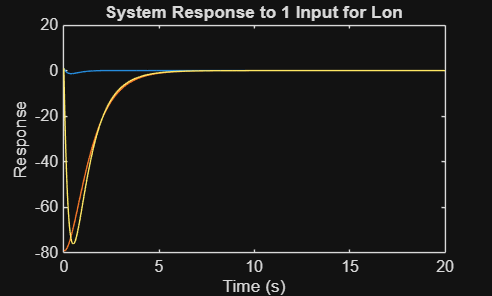


x11 = [1;
      1;
      1;
      1];

t = 0:0.01:20;

y = initial(Plon1, x11, t);
figure
plot(t, y);
xlabel('Time (s)');
ylabel('Response');
title('System Response to 1 Input for Lon');

Pentru lat

F_lat = -place(A_lat, B_lat, [-1 -2 -3 -4 -2])

F_lat =     5.4608   15.3151   10.4818   65.1011    0.4856
   -0.3343   14.0626   -1.4511    2.5609   -0.2048



disp(eig(A_lat + B_lat * F_lat))

  -4.0000 + 0.0000i
  -3.0000 + 0.0000i
  -1.0000 + 0.0000i
  -2.0000 + 0.0000i
  -2.0000 - 0.0000i



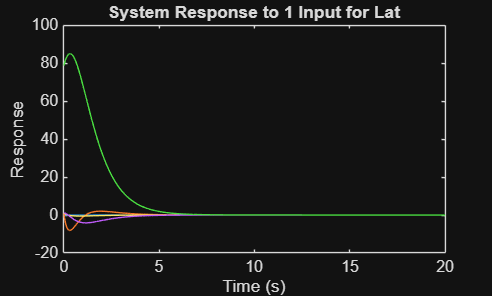


x12 = [1;
       1;
       1;
       1;
       1];

Plat1 = ss(A_lat + B_lat * F_lat, B_lat, C_lat, D_lat);
y_lat = initial(Plat1, x12, t);
figure
plot(t, y_lat);
xlabel('Time (s)');
ylabel('Response');
title('System Response to 1 Input for Lat');

### 
$$\left\lbrace -1-1-2-3\;\left(-\textrm{ceva}\right)\right\rbrace$$


Pentru lon

F_lon1 = -place(A_lon, B_lon, [-1 -1 -2 -3])

F_lon1 =     0.3187   -2.2357   -0.0173    0.0052
  -10.2072  -40.6892   -0.1587    0.1439



disp(eig(A_lon + B_lon * F_lon1))

   -3.0000
   -2.0000
   -1.0000
   -1.0000




Plon2 = ss(A_lon + B_lon * F_lon1, B_lon, C_lon, D_lon)


Plon2 =
 
  A = 
              x1         x2         x3         x4
   x1     -4.705     -6.434  -0.005259    0.01321
   x2          1          0          0          0
   x3     -102.2       -409     -1.591      1.485
   x4      74.93      13.76    -0.1179    -0.7039
 
  B = 
         u1    u2
   x1  -2.4  0.29
   x2     0     0
   x3  0.18   9.8
   x4  -6.5     0
 
  C = 
             x1        x2        x3        x4
   y1         1         0         0         0
   y2         0       -80    -0.028         1
   y3         0  -1.4e-13         1     0.029
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
 
Continuous-time state-space model.


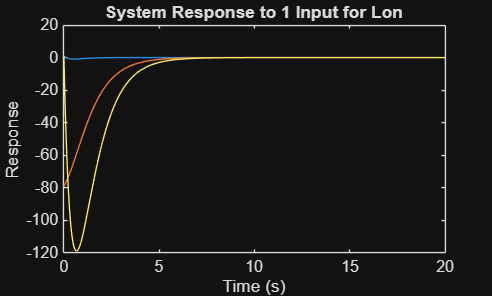


x11 = [1;
      1;
      1;
      1];

t = 0:0.01:20;

y1 = initial(Plon2, x11, t);
figure
plot(t, y1);
xlabel('Time (s)');
ylabel('Response');
title('System Response to 1 Input for Lon');

Pentru lat

F_lat1 = -place(A_lat, B_lat, [-1 -1 -2 -3 -2])

F_lat1 =     5.3223   10.7907   10.3607   60.7313    0.5465
   -0.2241    6.7149   -0.7885    1.1126   -0.0320



disp(eig(A_lat + B_lat * F_lat1))

   -3.0000
   -2.0000
   -2.0000
   -1.0000
   -1.0000



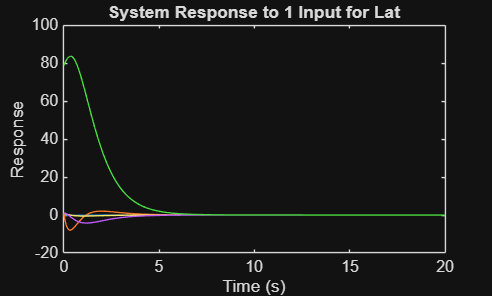


x22 = [1;
       1;
       1;
       1;
       1];

Plat1 = ss(A_lat + B_lat * F_lat1, B_lat, C_lat, D_lat);
y_lat1 = initial(Plat1, x22, t);
figure
plot(t, y_lat1);
xlabel('Time (s)');
ylabel('Response');
title('System Response to 1 Input for Lat');

### 
$$\left\lbrace -1-20-30-40\;\left(-\textrm{ceva}\right)\right\rbrace$$


Pentru lon

F_lon3 = -place(A_lon, B_lon, [-1 -20 -30 -40])

F_lon3 =    23.5094  340.0635   -0.7878   -1.0275
   -4.6487 -138.2126   -3.8861    1.9471



disp(eig(A_lon + B_lon * F_lon3))

   -1.0000
  -20.0000
  -30.0000
  -40.0000




Plon1 = ss(A_lon + B_lon * F_lon3, B_lon, C_lon, D_lon)


Plon1 =
 
  A = 
           x1      x2      x3      x4
   x1  -58.75  -856.2  0.7631   3.015
   x2       1       0       0       0
   x3  -43.53   -1303  -38.26   18.97
   x4  -75.81   -2211   4.891   6.009
 
  B = 
         u1    u2
   x1  -2.4  0.29
   x2     0     0
   x3  0.18   9.8
   x4  -6.5     0
 
  C = 
             x1        x2        x3        x4
   y1         1         0         0         0
   y2         0       -80    -0.028         1
   y3         0  -1.4e-13         1     0.029
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
 
Continuous-time state-space model.


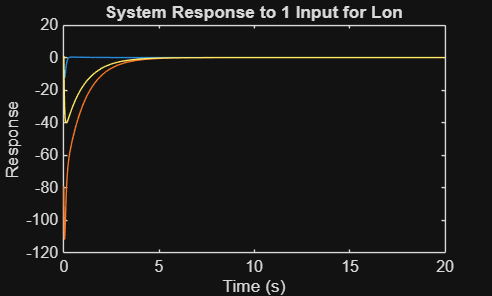


x31 = [1;
      1;
      1;
      1];

t = 0:0.01:20;

y2 = initial(Plon1, x31, t);
figure
plot(t, y2);
xlabel('Time (s)');
ylabel('Response');
title('System Response to 1 Input for Lon');

Pentru lat

F_lat3 = -place(A_lat, B_lat, [-1 -20 -30 -40 -20])

F_lat3 = 1.0e+03 *

    0.0585    0.5890    0.7558    8.1159    0.0896
   -0.0004    0.0282    0.0078    0.1245   -0.0199



disp(eig(A_lat + B_lat * F_lat3))

   -1.0000
  -40.0000
  -30.0000
  -20.0000
  -20.0000



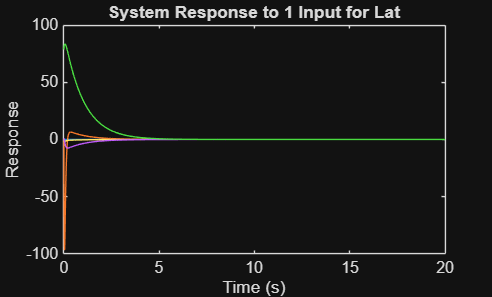


x32 = [1;
       1;
       1;
       1;
       1];

Plat1 = ss(A_lat + B_lat * F_lat3, B_lat, C_lat, D_lat);
y_lat2 = initial(Plat1, x32, t);
figure
plot(t, y_lat2);
xlabel('Time (s)');
ylabel('Response');
title('System Response to 1 Input for Lat');

g_lat = [1;
         1];

b = B_lat * g_lat

b =    -0.5500
   -0.3480
         0
         0
    2.0000



Ftilde = [1 1 1 1 1;
          1 1 1 1 1];
a = A_lat + B_lat * Ftilde

a =    -1.8500         0   -0.5500   -0.5500   -0.5740
   -0.2960   -0.8680   -0.3480   -0.3480   -0.3435
    1.0000    0.0280    0.0000         0         0
         0    1.0000    0.0000         0         0
    4.3000  -78.0000   11.8000    2.0000    1.8300



disp(rank(ctrb(a,b)))

     5



clear ans